# SNS Lab 10

## Syed Muhammad Asad Ali

### sa09475

#### Example (1)

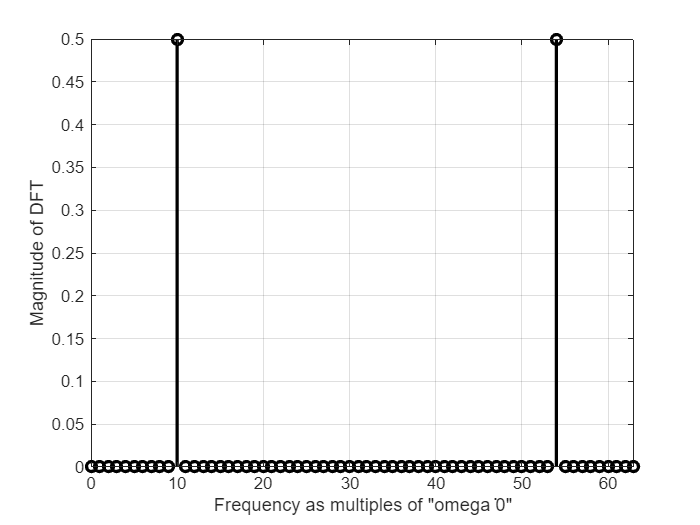

P = 64;
w = 2*pi/P;
n = 0:P-1;
x = cos(10*w*n); %Finite-time signal
hx = fft(x); %Compute the DFT of x
stem(n,abs(hx)/P,'k','LineWidth',2); %Compute and plot magnitude of coefficients
ylabel('Magnitude of DFT');
xlabel('Frequency as multiples of "omega ̇0"');
axis([0 P-1 0 inf]);
grid;

#### Example (2)

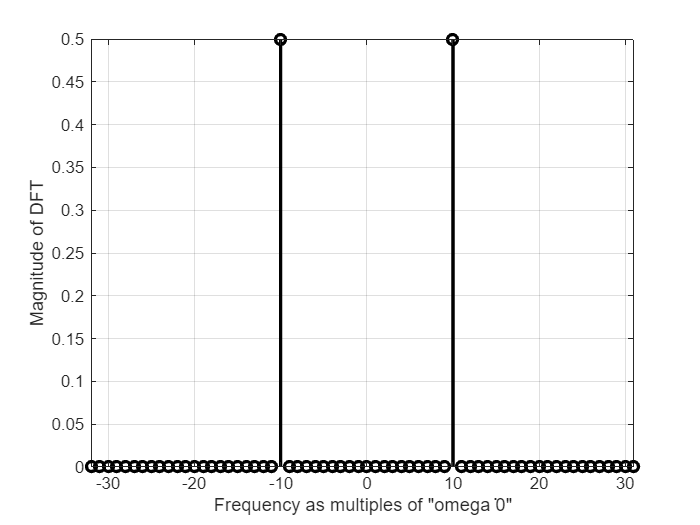

P = 64;
w = 2*pi/P;
n = 0:P-1;
x = cos(10*w*n); %Finite-time signal
hx = fft(x); %Compute the DFT of x
shx = fftshift(hx);
stem([-P/2:P/2-1],abs(shx)/P,'k','LineWidth',2);
ylabel('Magnitude of DFT');
xlabel('Frequency as multiples of "omega ̇0"');
axis([-P/2 P/2-1 0 inf]);
grid;

#### Task 1(a)

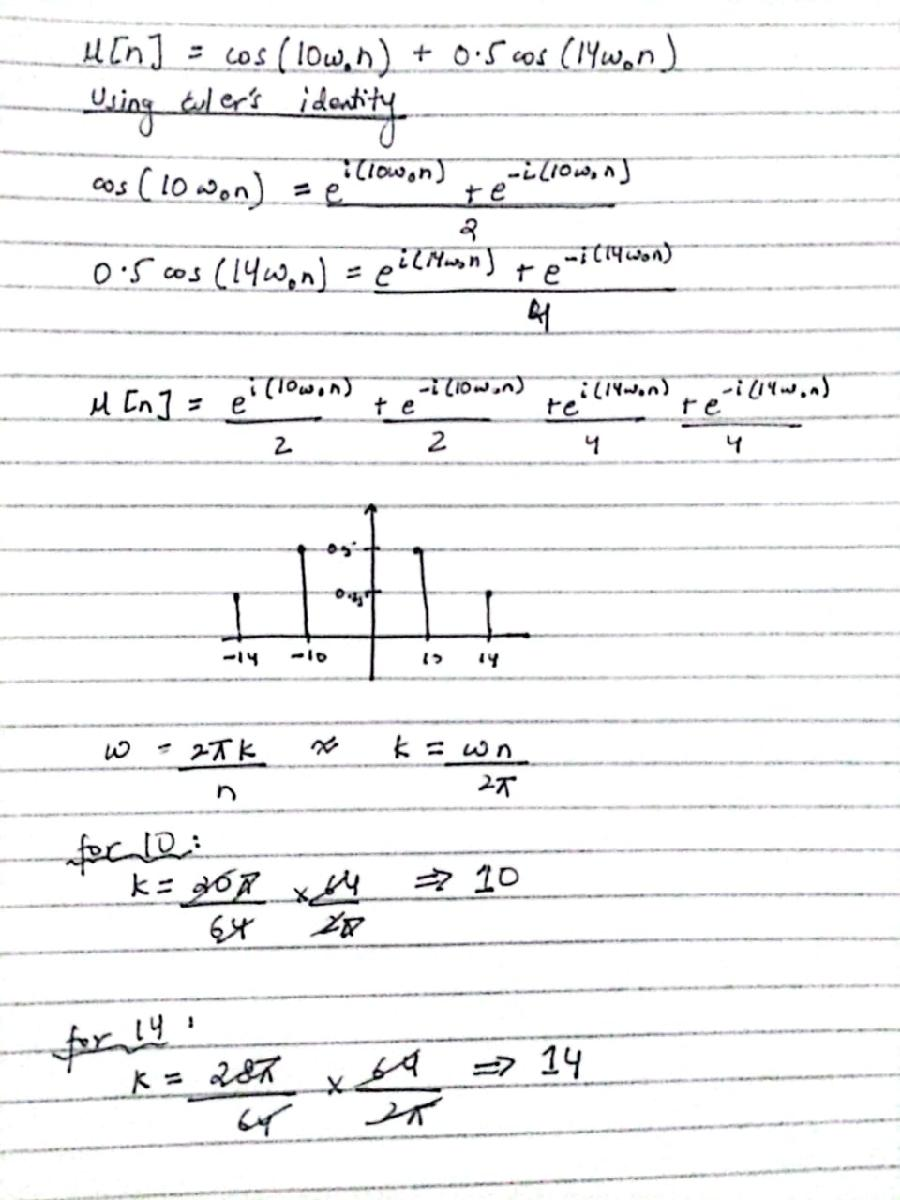

#### Task 1(b)

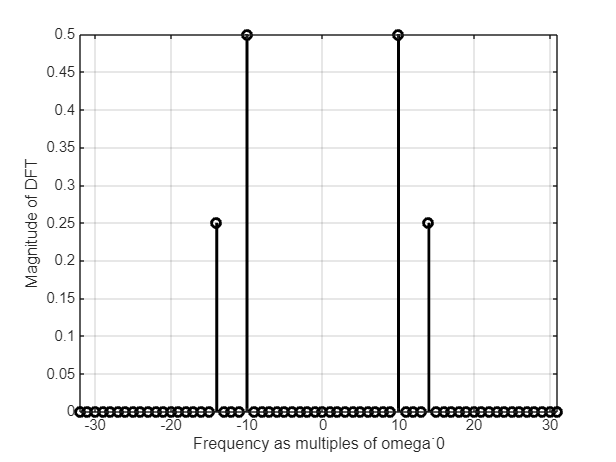

P = 64;
w = 2*pi/P;
n = 0:P-1;
x = cos(10*w*n) + 0.5*cos(14*w*n); %Finite-time signal
hx = fft(x); %Compute the DFT of x
shx = fftshift(hx);
stem([-P/2:P/2-1],abs(shx)/P,"k","LineWidth",2);
ylabel("Magnitude of DFT");
xlabel("Frequency as multiples of omega˙0");
axis([-P/2 P/2-1 0 inf]);
grid;

## Task 2

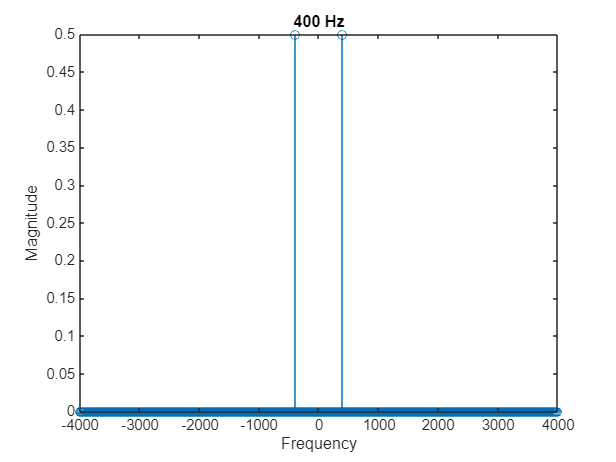

clc;
clear;
close all;

fs= 8000;
f= 400;
n= 1000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);

hx=fft(x);
shx=fftshift(hx);

fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("400 Hz");
ylabel("Magnitude");
xlabel("Frequency");

Yes the output is what we would expect it to be.

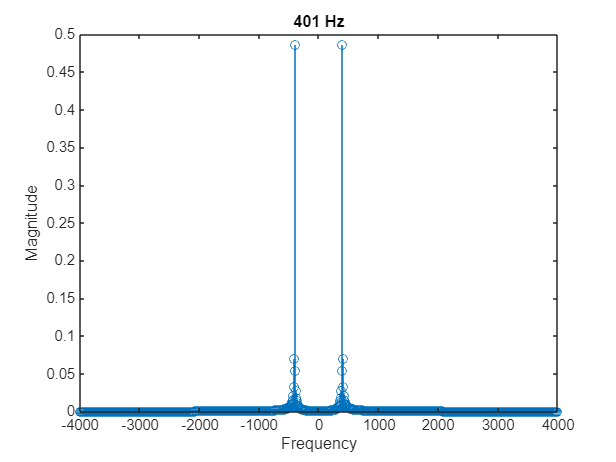

fs= 8000;
f= 401;
n= 1000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("401 Hz")
ylabel("Magnitude");
xlabel("Frequency");

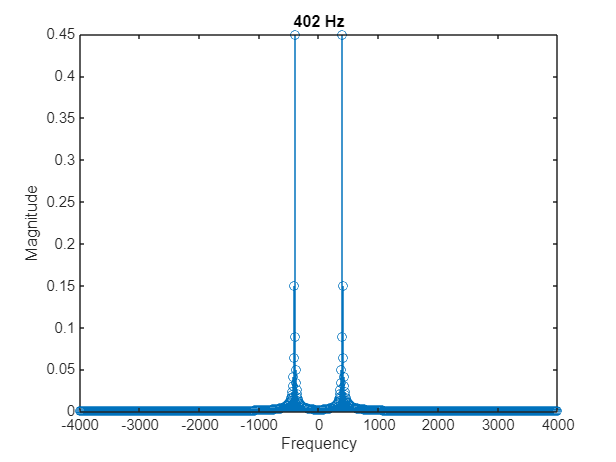


fs= 8000;
f= 402;
n= 1000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("402 Hz")
ylabel("Magnitude");
xlabel("Frequency");

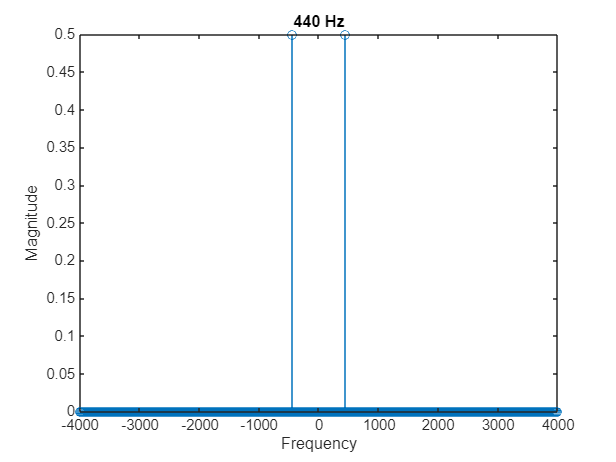


fs= 8000;
f= 440;
n= 1000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("440 Hz")
ylabel("Magnitude");
xlabel("Frequency");

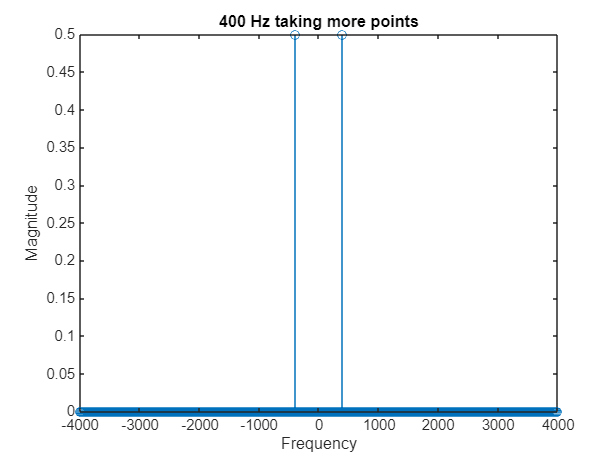

fs= 8000;
f= 400;
n= 5000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x,n);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("400 Hz taking more points");
ylabel("Magnitude");
xlabel("Frequency");

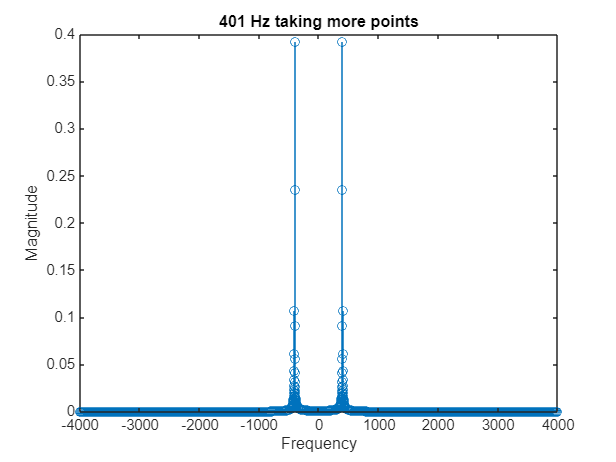


fs= 8000;
f= 401;
n= 5000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x,n);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("401 Hz taking more points");
ylabel("Magnitude");
xlabel("Frequency");

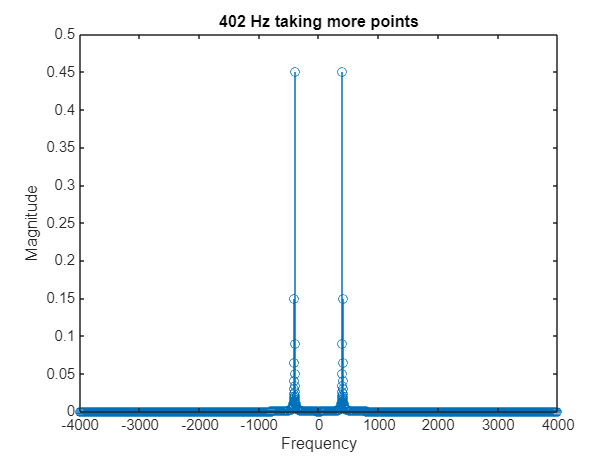


fs= 8000;
f= 402;
n= 5000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x,n);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("402 Hz taking more points");
ylabel("Magnitude");
xlabel("Frequency");

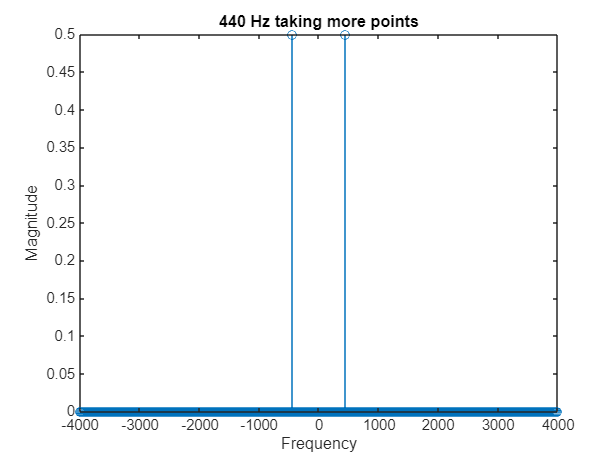


fs= 8000;
f= 440;
n= 5000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x,n);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("440 Hz taking more points");
ylabel("Magnitude");
xlabel("Frequency");

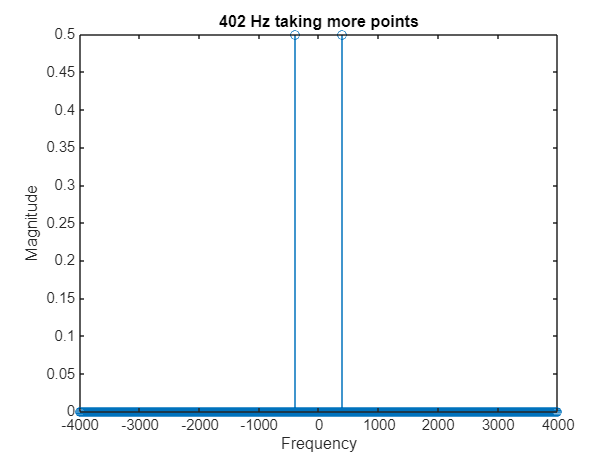

fs= 8000;
f= 402;
n= 4000;
t= (0:n-1)/fs;
x= sin(2*pi*f*t);
hx=fft(x,n);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("402 Hz taking more points");
ylabel("Magnitude");
xlabel("Frequency");

#### Task 3

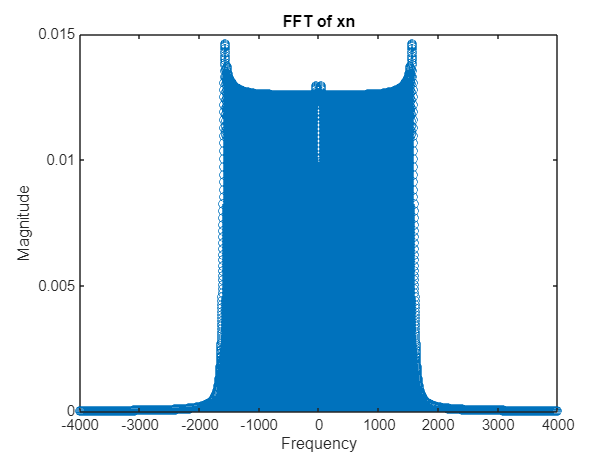

clc;
clear; 
close all;

fs=8000;
n=8000;
t=(0:n-1)/fs;
xn = sin(2*pi*800*t.^2);
hx=fft(xn);
shx=fftshift(hx);
fHz= fs*(-n/2:n/2-1)/n;
figure;
stem(fHz,abs(shx)/n)
title("FFT of xn");
ylabel("Magnitude");
xlabel("Frequency");

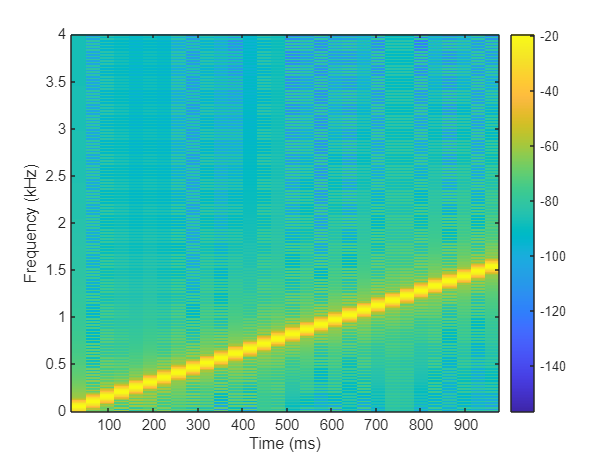

spectrogram(xn,512,[],1024,fs,"yaxis");
colorbar

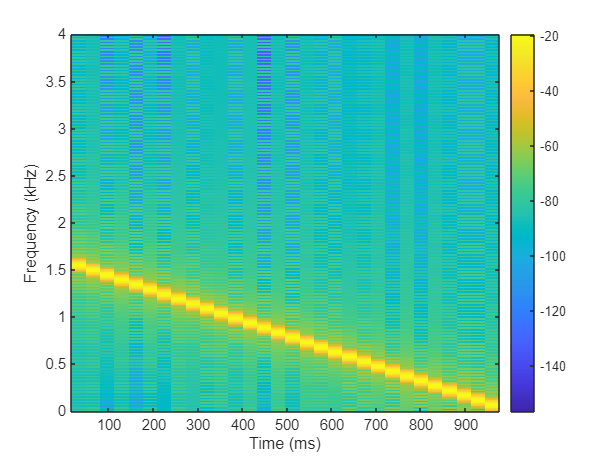

xtuu= xn(8000:-1:1);
spectrogram(xtuu,512,[],1024,fs,"yaxis");
colorbar